%{
ES115 Engineering Computer Applications
Module 7 Project: Streetlight Brightness Model

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models and compares the brightness of two streetlights along
a road using quadratic functions. Each streetlight has its own position,
maximum brightness, and spread. The goal is to visualize how brightness
changes with distance, determine where each light is brightest, and find
where both lights produce approximately the same brightness.

Inputs (Knowns):
- Position values (x) from -20 to 20
- Streetlight 1 model: B1(x) = -k1(x - h1)^2 + Bmax1
    • k1 = 0.2, h1 = -5, Bmax1 = 50
- Streetlight 2 model: B2(x) = -k2(x - h2)^2 + Bmax2
    • k2 = 0.15, h2 = 5, Bmax2 = 60

Outputs (Unknowns):
- Brightness values for both streetlights
- Graph comparing brightness along the road
- Maximum brightness and location for each light
- Approximate intersection point(s) where brightness is equal

Engineering Workflow and Algorithms:
- Define position values along the road
- Create quadratic models for both streetlights
- Evaluate brightness values over the range
- Plot both brightness functions on the same graph
- Use MATLAB functions to find maximum brightness values
- Compare both models to find where their outputs are approximately equal

MATLAB Tools / Functions Used:
- plot() for graphing
- max() to find maximum brightness
- find() to locate intersection points
- abs() for approximate equality comparison
- indexing to match values with positions
- fprintf() and disp() for displaying results
- element-wise operations (.^) for calculations

Reflection After Completing the Project:
- I learned how quadratic models can represent real-world situations like
  light intensity and how changing parameters affects the graph.
- I also understood how the vertex represents the maximum brightness and
  how to compare two models to find where they overlap.
- If I were to improve this, I would solve for the exact intersection point
  instead of estimating it.
- Difficulty Rating: 5/10 — the setup was straightforward, but comparing
  both models and interpreting the results took some thought.
%}



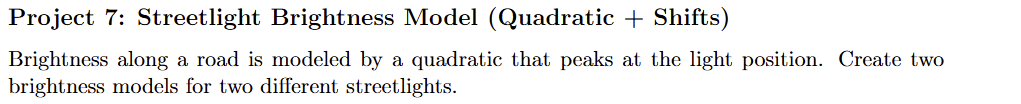

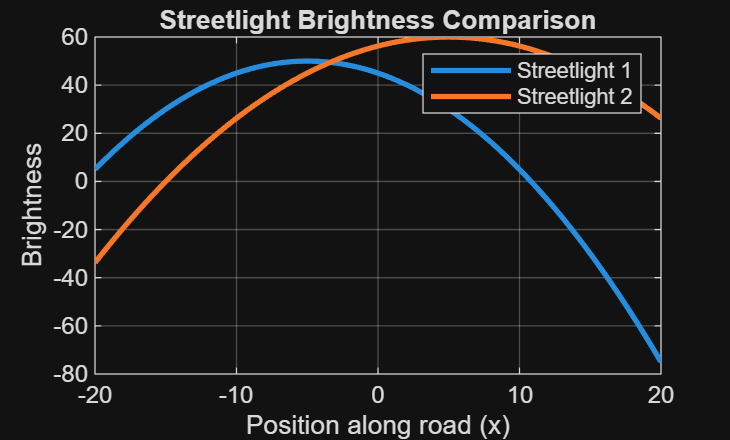

 
clear; clc; close all; 
 
% ---------------------------- 
% Define x values (road position) 
x = -20:0.5:20; 
 
% ---------------------------- 
% Streetlight 1 parameters 
k1 = 0.2; 
h1 = -5; % location of light 
Bmax1 = 50; % max brightness 
 
B1 = -k1*(x - h1).^2 + Bmax1; 
 
% ---------------------------- 
% Streetlight 2 parameters 
k2 = 0.15; 
h2 = 5; % different location 
Bmax2 = 60; % brighter light 
 
B2 = -k2*(x - h2).^2 + Bmax2; 
 
% ---------------------------- 
% Plot both brightness models 
figure; 
plot(x, B1, 'LineWidth', 2); hold on; 
plot(x, B2, 'LineWidth', 2); 
 
title('Streetlight Brightness Comparison'); 
xlabel('Position along road (x)'); 
ylabel('Brightness'); 
legend('Streetlight 1', 'Streetlight 2'); 
grid on; 

 
% ---------------------------- 
% Find maximum brightness points 
 
[max1, idx1] = max(B1); 
x1 = x(idx1); 
 
[max2, idx2] = max(B2); 
x2 = x(idx2); 
 
fprintf('Streetlight 1 max brightness: %.2f at x = %.2f\n', max1, x1); 

Streetlight 1 max brightness: 50.00 at x = -5.00


fprintf('Streetlight 2 max brightness: %.2f at x = %.2f\n', max2, x2); 

Streetlight 2 max brightness: 60.00 at x = 5.00


 
% ---------------------------- 
% Find approximate intersection (equal brightness) 
 
difference = B1 - B2; 
index_intersect = find(abs(difference) < 0.5); 
 
x_intersect = x(index_intersect); 
 
disp('Approximate intersection point(s):'); 

Approximate intersection point(s):


disp(x_intersect)

   -3.5000

